% Helper Functions
function a = get_a(t,amax,t_ahold,t_vhold)
    a = zeros(size(t));
    
    idx1 = (0 <= t) & (t < t_ahold);
    idx2 = ((t_ahold <= t) & (t < (t_ahold + t_vhold)));
    idx3 = (((t_ahold + t_vhold) <= t) & (t < (2*t_ahold + t_vhold)));
    
    a(idx1) = amax;
    a(idx2) = 0;
    a(idx3) = -amax;
end

function [a,v,s] = get_kin_functions(dt,t,amax,t_ahold, t_vhold, delta_s)
    a = get_a(t,amax,t_ahold,t_vhold) * sign(delta_s);
    v = cumsum(a) * dt;
    s = cumsum(v) * dt;
end

function t_ahold = get_t_ahold_without_t_vhold(delta_s,amax)
    t_ahold = sqrt(abs(delta_s) / amax);
end

function [t_ahold, t_vhold] = get_tahold_and_tvhold(delta_s,amax,vmax)
    tahold_without_tvhold = get_t_ahold_without_t_vhold(delta_s, amax);

    if tahold_without_tvhold * amax > vmax
        t_ahold = vmax / amax;
        t_vhold = abs(delta_s) / vmax - vmax / amax;
    else
        t_ahold = tahold_without_tvhold;
        t_vhold = 0;
    end
end

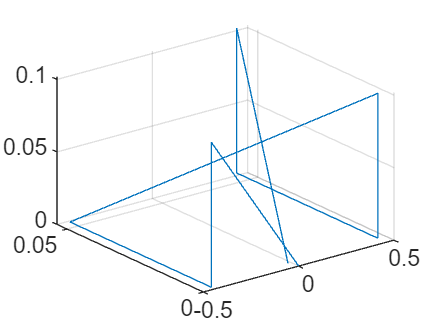

close all; clear;

dim = 4;    % Specify dimensions

dt = 0.001; % Time Resolution = 1ms

% Initialize Vectors
t = [];
a = zeros([dim 0]);
v = zeros([dim 0]);
s = zeros([dim 0]);

% Masses of axes
m_x = 6.905;
m_y = 1;
m_z = .5;

% Acceleration limit
a_max_val = 40;
amax = [a_max_val a_max_val a_max_val 100000];

% Velocity limit
v_mot = 1000;
vmax = [v_mot v_mot v_mot 100000];

% Dimensions of Conveyor Belts
dist_to_belt = .45; % 450cm
depth_to_pickup = 0.05;
height_over_belt = .1; % 100cm

% Define endeffector path
positions = [
    [0,                         0,                                 0,    0],
    [-dist_to_belt,             0,                  height_over_belt,    0],
    [-dist_to_belt,             0,                                 0,    0],
    [-dist_to_belt,            depth_to_pickup,                    0,    0],
    [ dist_to_belt,             0,                  height_over_belt,   pi],
    [ dist_to_belt,             0,                                 0,   pi],
    [ dist_to_belt,             depth_to_pickup,                   0,   pi],
    [ dist_to_belt,             depth_to_pickup,    height_over_belt,   pi],
    [0,                         0,                                 0,    0],
    ];

positions_size = size(positions);
num_of_positions = positions_size(1);

% Calculate kinematics for each position delta
for i = [1:num_of_positions - 1]
    position = positions(i,:);
    next_position = positions(i + 1,:);

    delta_position = next_position - position;

    longest_time_i = 1;
    longest_time = 0;
    longest_t_ahold = 0;
    longest_t_vhold = 0;

    % Find longest time taken
    for j = 1:dim
        [t_ahold, t_vhold] = get_tahold_and_tvhold(delta_position(j), amax(j), vmax(j));
        t_tot = 2 * t_ahold + t_vhold;

        if t_tot > longest_time
            longest_time_i = j;
            longest_time = t_tot;
            longest_t_ahold = t_ahold;
            longest_t_vhold = t_vhold;
        end
    end

    t_temp = 0:dt:longest_time;

    % Calculate kinematics for each axis
    for i = 1:dim
        amax_temp = amax(i);
        vmax_temp = vmax(i);

        % Check whether velocity exceeds limit with max acceleration
        if (longest_time / 2) * amax_temp > vmax_temp
            ta_temp = vmax_temp / amax_temp;
            tv_temp = longest_time - 2 * ta_temp;

            v_peak_temp = abs(delta_position(i)) / (ta_temp + tv_temp);
            a_peak_temp = v_peak_temp / ta_temp;
        else
            tv_temp = 0;
            ta_temp = longest_time / 2;
            a_peak_temp = abs(delta_position(i)) / (ta_temp^2);
        end

        [a_temp,v_temp,s_temp] = get_kin_functions(dt,t_temp, a_peak_temp,ta_temp, tv_temp, delta_position(i));

        % Append a v s data to previous
        a(i, length(t) + 1: length(t) + length(a_temp)) = a_temp;
        v(i, length(t) + 1: length(t) + length(v_temp)) = v_temp;

        if ~isempty(t)
            s(i, length(t) + 1: length(t) + length(s_temp)) = s_temp + s(i, length(t));
        else
            s(i, length(t) + 1: length(t) + length(s_temp)) = s_temp + positions(1,i);
        end
    end

    if ~isempty(t)
        t(end + 1: end + length(t_temp)) = t_temp + t(end);
    else
        t(end + 1: end + length(t_temp)) = t_temp;
    end
end


% Generate Plots
if dim == 2
    plot(s(1,:),s(2,:))
elseif dim == 3 | dim == 4
    plot3(s(1,:),s(2,:),s(3,:))
end
grid on;

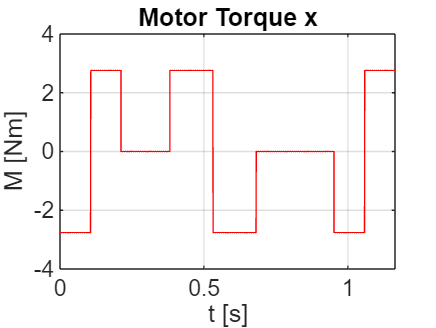

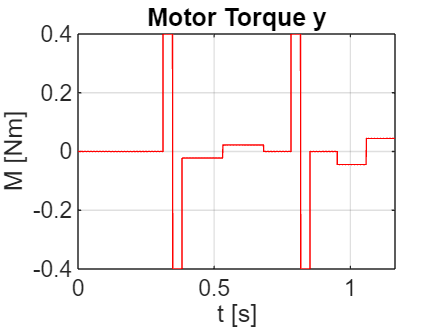

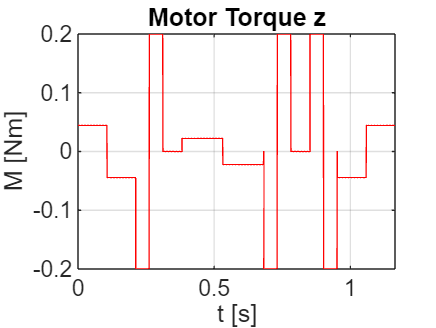


m = [m_x m_y m_z];
r = 0.01;
labels = ["x","y","z"];

for i = 1:(dim - 1)
    figure();
    plot(t, r * m(i) .* a(i,:), "r"); grid on;
    xlabel("t [s]");
    ylabel("M [Nm]");
    title(sprintf("Motor Torque %s", labels(i)))
end

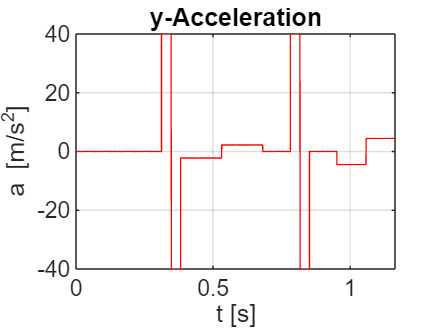


i = 2;
figure()
plot(t, a(i,:), "r"); grid on;
xlabel("t [s]");
ylabel("a [m/s^2]");
title("y-Acceleration")

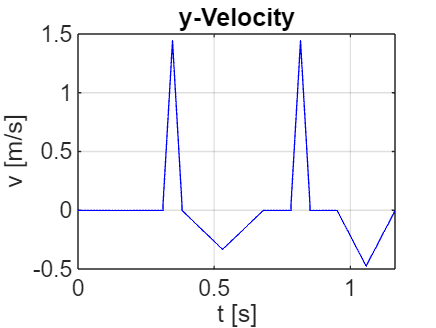


figure()
plot(t, v(i,:), "b"); grid on;
xlabel("t [s]");
ylabel("v [m/s]");
title("y-Velocity")

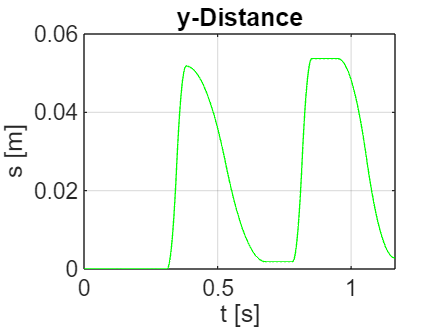


figure()
plot(t, s(i,:), "g"); grid on;
xlabel("t [s]");
ylabel("s [m]");
title("y-Distance")

% Abgabe 3
close all;

D = 5e-2;

M_x = m_x * a(1,:) * D / 2;
omega_x = v(1,:) / (D / 2);
N_x = omega_x * 60 / 2 / pi;

P_x = abs(M_x .* omega_x)

P_x = 1.0e+03 *

    0.0110    0.0221    0.0331    0.0442    0.0552    0.0663    0.0773    0.0884    0.0994    0.1105    0.1215    0.1326    0.1436    0.1547    0.1657    0.1768    0.1878    0.1989    0.2099    0.2210    0.2320    0.2431    0.2541    0.2652    0.2762    0.2872    0.2983    0.3093    0.3204    0.3314    0.3425    0.3535    0.3646    0.3756    0.3867    0.3977    0.4088    0.4198    0.4309    0.4419    0.4530    0.4640    0.4751    0.4861    0.4972    0.5082    0.5193    0.5303    0.5414    0.5524



sum(P_x) * dt / t(end)

ans = 430.8910

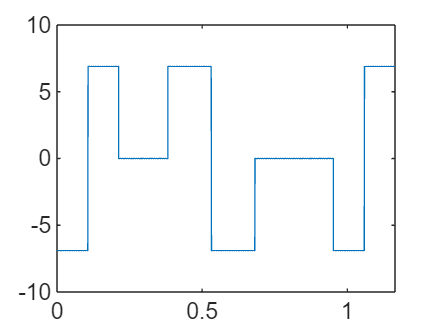


plot(t, M_x)

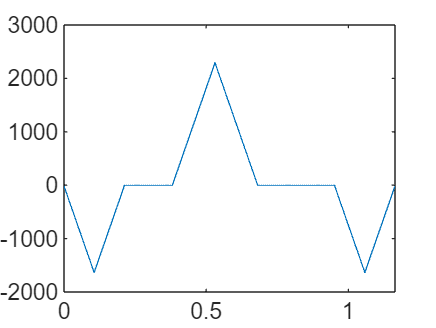

plot(t, N_x)

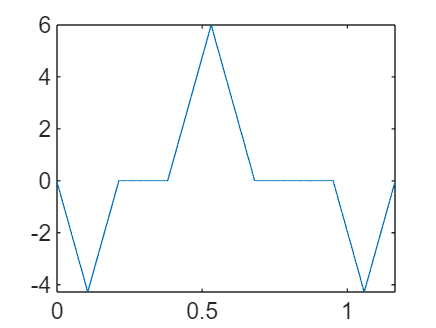

plot(t, v(1,:))

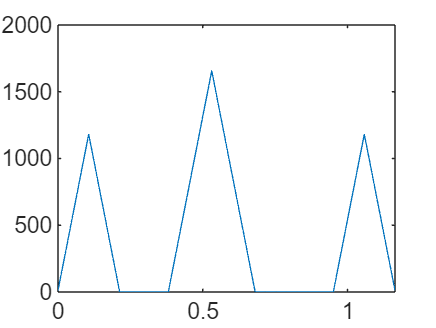

plot(t,P_x)